# Lights spiral

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Standard textures

%     DMFWood6
%     NBglass            (Norm Bowler)
%     NBoldglass         (Norm Bowler)
%     NBwinebottle       (Norm Bowler)
%     NBbeerbottle       (Norm Bowler)
%     Ruby_Glass         (after Norm Bowler)
%     Dark_Green_Glass   (after Norm Bowler)
%     Yellow_Glass       (after Norm Bowler)
%     Orange_Glass       (after Norm Bowler)
%     Vicks_Bottle_Glass (after Norm Bowler)
%     Soft_Silver        (Dan Farmer)
%     New_Penny          (Dan Farmer)
%     Tinny_Brass        (Dan Farmer)
%     Gold_Nugget        (Dan Farmer)
%     Aluminum           (Dan Farmer)
%     Bright_Bronze      (Dan Farmer)
%     Lightening1        (Dan Farmer)
%     Lightening2        (Dan Farmer)
%     Brushed_Aluminum   (Dan Farmer)
%     Starfield          (Jeff Burton )
%     Shadow_Clouds      (Bill Pulver)

#### Create scene

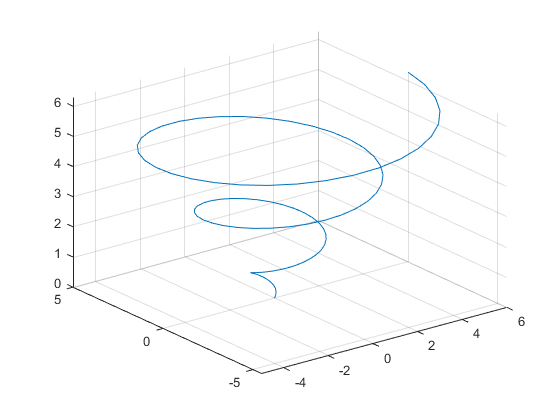

pl.scene_begin('scene_file', 'lights_spiral.pov', 'image_file', 'lights_spiral.png');
    pl.include("shapes");
    pl.global_settings("assumed_gamma 1");
    
    pl.camera('angle', 25, 'location', [22 18 13], 'look_at', [0 -0.8 4], 'type', 'perspective');
    %pl.light('location',  [0 0 0], 'color', [1 1 1]);
    pl.axis('length', [10 10 10]);
    
    % Axis planes
%     tex_plane_red   = pl.declare("tex_plane_red",   pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
%     tex_plane_green = pl.declare("tex_plane_green", pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
%     tex_plane_blue  = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% 
%     pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_red',  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%     pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green, 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%     pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_blue,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
    
    % Light marks
    nmarks = 100;
    
    % Create
    r = linspace(0,1,nmarks);
    theta = linspace (0, 6*pi, nmarks);
    x = r.*cos(theta) * 6;
    y = r.*sin(theta) * 6;
    z = theta / 3;
    
    % Draw
    figure(1)
    plot3(x, y, z)
    grid on


    for n = 1:nmarks
        g =  (n / nmarks) / 1.5;
        pl.sphere('position', [x(n) y(n) z(n)], 'radius', 0.2, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
        % pl.light('location',  [x(n) y(n) z(n)], 'color', [g g g]);
        pl.light('location',  [x(n) y(n) z(n)], 'color', [g 1-g g]);
    end
% 
% 
% 
%     s = 4;
%     e = 14;
%     n = e - s;
%     for y = s:e
%         r =  ((y - s) / n);
%         pl.sphere('position', [2 y 2], 'radius', 0.4, 'texture', 'Yellow_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         % pl.light('location',  [2 y 2], 'color', [0.4 g 0.4]);
%         pl.light('location',  [2 y 2], 'color', [r 0.4 0.4]);
%     end
% 
%     for y = s:e
%         g =  ((y - s) / e);
%         pl.sphere('position', [2 y 3], 'radius', 0.4, 'texture', 'Dark_Green_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 3], 'color', [0.4 g 0.4]);
%     end
% 
%     for y = s:e
%         g =  ((y - s) / e);
%         pl.sphere('position', [2 y 4], 'radius', 0.4, 'texture', 'NBwinebottle', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 4], 'color', [0.4 g 0.4]);
%     end
% 
%     for y = s:e
%         g =  ((y - s) / e);
%         pl.sphere('position', [2 y 5], 'radius', 0.4, 'texture', 'NBoldglass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 5], 'color', [0.4 g 0.4]);
%     end
% 
%     for y = s:e
%         r =  ((y - s) / e);
%         pl.sphere('position', [2 y 6], 'radius', 0.4, 'texture', 'NBglass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 6], 'color', [r 0.4 0.4]);
%     end
% 
%     for y = s:e
%         r =  ((y - s) / e);
%         pl.sphere('position', [2 y 7], 'radius', 0.4, 'texture', 'Orange_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 7], 'color', [r 0.4 0.4]);
%     end
% 
%     for y = s:e
%         r =  ((y - s) / e);
%         pl.sphere('position', [2 y 8], 'radius', 0.4, 'texture', 'Vicks_Bottle_Glass', 'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);
%         pl.light('location',  [2 y 8], 'color', [r 0.4 0.4]);
%     end
    
pl.scene_end();

#### Render scene and show image

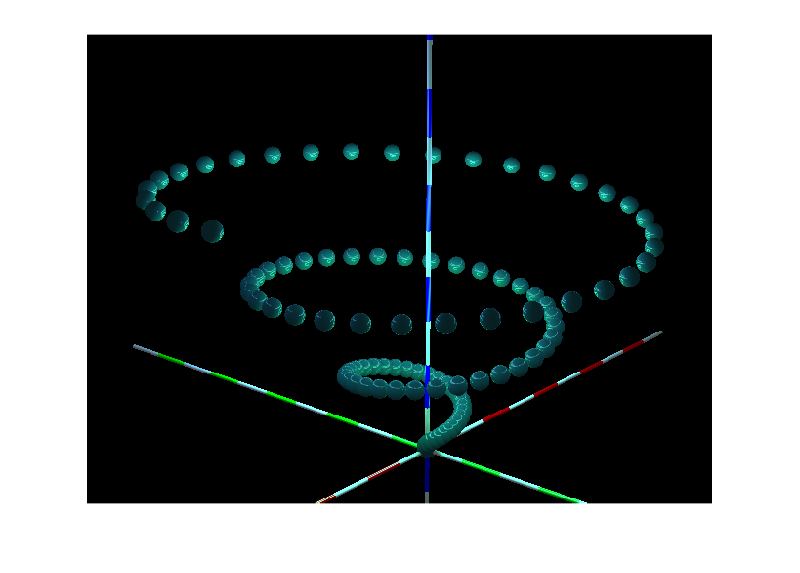

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 3.730240 seconds.
